# Решение  одномерной обратной задачи нестационарной теплопроводности методом конечных разностей

## Некоторые общие сведения и терминология 

Если принять граничные условия, свойства материалов, внутренние источники тепла и геометрию объектов за **причину** теплобмена, а тепловое состояние  объекта за **следствие**, то  найти следствие по причине - это **прямая задача**, а причину по следствию - **обратная**.

Так как процесс теплоперенса протекает во времени, нельзя поставить эксперимент по измерению непосредственно **причины, **отсюда следует "физическая" некорректность постановки обратных задач.

Обратные задачи можно разделить на три класса:

- идентификации тепловых процессов

- проектирования

- управления процессами

Принципиальным отличием первой задачи от второй и третьей можно назвать то, что для последних, наличие множества "верных" решений (**некорректность**) это хорошо, так как годится любое решение, удовлетворяющее техническому результату  с заданной точностью. Пример - расчет многослойных структур для диэлектрики,  существует много различных структур удовлетворяющих заданной частотной зависимости. Тоже самое и с задачей управления, если решения ОЗ возвращает управляющйи сигнал, который дает нужный отклик, то нам этого достаточно. В случае идентификации множественность решений усложняет ситуацию, так, как истинная причина теплового состояния системы была одна. Например, может быть что измеренной в некоторых точках темперутре образца соотвествует множество кривых для температурной зависимости теплопроводности, тогда возникает вопрос как выбрать одну из множества (**регуляризация**).

Постановку задач можно разделить на два класса:

- с сосредоточенными (lumped) параметрами (задачи теплообмена)

- с распределенными (disctributed) параметрами (задачи теплопроводности)

Первый класс задач строится на представлении системы как совокупности отдельных объектов, которые взаимодействуют через интерфейсы, развитие этой системы во времени сводится к решению системы обыкновенных дифференциальных или дифференциально-алгебраических уравнений (matlab simulink, julia dyad). Причем, отдельные блоки внутри могут решать и уравнения в частных производных.

Например, если у нас есть $N$ изотермических элементов (то есть, каждый отдельный элемент характеризуется некоторой одной температурой), $r$ элементов при этом взаимодействуют в окружающей средой через конвекцию, а $s$  - через излучение, кроме того в каждом $n$-м элементе может выделяться тепло $Q_n$, тогда, согласно закону сохранения энергии, скорость изменения запасенного количества теплоты для каждого элемента определяется балансом поступающего к нему извне и отдаваемому им вовне тепла:

$C_n \frac {dT_n}{dt} = \Sigma_{j=1}^{N+r}\lambda_{jn}(T_j - T_n) + \Sigma_{j=1}^{N+s}K_{nj}\sigma(T_j^4 - T_n^4)A_n + Q_{n}$                                         (1)


$$n \in [1...N]$$


В уравнении выше, "причинами" являются взаимосвязи между элементами и температуры окружающего пространства, а "следствиями"  - зависимости температур элементов от времени.

$C_n$ - теплоемкость, $T_n$ - температуры элементов, $T_r$ - температуры "восстановления" окружающего пространтва, $\lambda_{jn}$ - коэффициенты теплоотдачи как взаимные между элементами, так и между элементами и окружающей средой (в общем случае каждый

элемент может быть окружен средой со своей темепратурой востановления и коэффициентом теплоотдачи), $K_{nj}$ -  коэффициенты облучения, зависящие в общем случае от угловых коэффициентов $F_{jn}$ (view factors) и излучательных способностей объектов $\epsilon_{n}$ и $\epsilon_{j}$, $A_n$ - площадь обекта, $Q_n$ - внутренние источники тепла.

Уравнение (1) может быть вкратце переписано как нелинейное обыкновенное дифференциальное уравнение:


$$\frac {d\vec{T}}{dt} = \Phi (\vec{T})$$


Здесь $\vec{T} = \matrix { T_i \cr \vdots \cr T_N}$, а $\Phi$ - некоторый нелинейный в общем случае оператор, который возвращает вектор равный по размеру вектору $\vec{T}$.

Второй класс обратных задач (задачи с распределенными параметрами) построен на решении дифференциальных уравнений в частных производных (ДУЧП), второй сводится к решению обыкновенных дифференциальных уравнений. "Причиной" при решении ДУЧП служат начальные условия, граничные условия, коэффициенты уравнения,  внутренние источники. Поэтому и ОЗ для систем с распределенными разделяют на:

- **Ретроспективные** (нахождение температуры в предудущие моменты времени)

- **Граничные** (найти условия на границе)

- **Коэффициентные** (например, найти теплопроводность)

Также можно поставить задачи **геометрические**, например, в одномерной случае это может быть нахождение глубины протекания реакции, зависящей от негрва, такой, как, например термическая деструкция. И задачу на отыскание внутренних источников тепла, примером которой также может служить термодеструкция в процессе нагрева.

## Условие (математической) корректности задачи по Адамару и метод регуляризации Тихонова

## 
$$Au=f$$
 

- Решение существует для $\forall f \in F$(условие разрешимости)

- Решение единственно (условие однозначности)

- Решение непрерывно зависит от входных параметров (устойчиво), $u$ непрерывно зависит от $f$. То есть, небольшие изменения входных параметров не должны приводить к "большим" изменениям выходных.

#### Пример:  СЛАУ

Посмотрим эти критерии на примере простой обратной задачи - обращения линейного оператора:

$A\vec{b}=\vec{y}$                                                                                                            (2)

Если матрица $A$ квадратная, то в случае, если она несингулялрна она удовлетворяет всем условиям корреткности , если же $A$ сингулярна (ранг матрицы меньше размерности пространства ее столбцов, то есть, ее нуль-пространство является нетривиальным), то задача некорректна.  

Причем, если $\vec{y} \in \mathbb{N}(A^T)$ (принадлежит нуль-пространству матрицы $A^T$), то задача решения не имеет (то есть не корректна по первому критерию), а если $\vec{y}\in \mathbb{C}(A)$ (лежит в пространстве столбцов, то задача имеет бесконечно много решений), то есть, такого рода задача не удовлетворяет второму критерию. 

Для неквадратной матрицы с линейно независимыми столбцами ситуация аналогична, задача имеет решение, только если вектор $\vec{y} \in \mathbb{C}(A)$.

Таким образом если задача (2) сформулирована в общем виде, без ограничений на вектор $\vec{y}$ и матрицу $A$, такая постановка задачи будет некорректной.

Теперь посмотрим задачу линейной регрессии :


$$argmin(||A\vec{b}-\vec{y}||_2^2)$$


Обычно матрица $A$ имеет больше строк, чем столбцов.

 Как известно, решение этой задачи для матриц полного ранга дается  $\vec{b}=A^{\dagger}\vec{y} = (A^TA)^{-1}A^T\vec{y}$,  вектор ошибки $\vec{e}= \hat y - \vec{y} = A\vec{b} - \vec{y} $  , причем $\vec{e} \in \mathbb{N}(A^T)$.

 В этом случае задача будет иметь единственное решение и будет корректной. Если же ранг матрицы$A$ меньше числа ее столбцов, матрица $A^TA$ будет необратимой и задача будет некорректной по Адамару, так как имеет бесконечно много решений. 

A = [1 2 3;1 2 -3;2 4 0] % матрица с двумя зависимыми столбцами
y = [3;3;3] 
A\y % левостороннее деление решает задачу методом QR - факторизации

Тут нужно отметить, что псевдообратная матрица (матрица Мура-Пенроуза) в случая сингулярной матрицы $А$ все равно существует.  Псевдообратная матрица для матриц неполного ранга рассчитывается через SVD разложение:

$A = U\Sigma V^T$, а для обратной матрицы $(A^T A)^{-1}A^T=(V\Sigma U^T U \Sigma V^T)^{-1}V \Sigma U^T = V \Sigma ^{-2} V^T (V \Sigma U^T) = V \Sigma ^{-2} \Sigma U^T $.

Таким образом, если матрица несингулярная то у нее нет нулевых сингулярных значений и псевдообратная матрица будет просто $A^{\dagger} =V \Sigma ^{-1}  U^T $.

Однако, сингулярное разложение матрицы неполного ранга  будет иметь среди сингулярных значений ноль. Поэтому при расчете $A^{\dagger}$ выкидывают все сингулярные значения равные нулю и соотвествующие им левые и правые сингулярные вектора:

$A^{\dagger} = V\Sigma ^{\dagger} U^T$ (для полноранговой матрицы $\Sigma ^{\dagger} = \Sigma ^{-1}$, а $A^{\dagger} = (A^T A)^{-1}A^T$)

$\Sigma ^{\dagger} = [\matrix{\frac{1}{\sigma_1}  &&&&0\cr
&\ddots \cr
& &\frac{1} {\sigma_i} &  \cr
&&&\ddots \cr
0&&&&0  &  \cr
}]$ (нули для всех $\sigma_n =0$)

[u,s,v] = svd(A) % сингулярное разложение исходной матрицы 

A =      1     2     3
     1     2    -3
     2     4     0


A = u*s*v' 

y =      3
     3
     3


Sigma_dagger = inv(s(1:2,1:2))

ans =       -Inf
       Inf
    0.5000


A_dagger_manual  = v(:,1:2)*Sigma_dagger*u(:,1:2)'
A_dagger = pinv(A) 
b_pseudoinverse = pinv(A)*y % псевдообратная матрица находится при помощи SVD разложения

Так как число решений для матрицы неполного ранга бесконечно, решение при помощи псевдообратной матрицы $A^{\dagger}\vec{y}$ для этого случая возвращает значение $\vec{b}$, которое имеет минимальную норму среди прочих.

Если же решать эту задачу итерационным методом оптимизации, то методы нулевого  (например Нелдера-Мида) и первого порядка (например, градиентного спуска) будут давать различные решения для различных стартовых условий ( у алгоритма нет признака, по которому он мог бы выбрать из бесконечного множества решений один локальный минимум), а метод второго порядка (например метод Ньютона) будет выдавать ошибку, так как матрица Гесса ($H=A^TA$) данном случае необратима (а шаг алгоритма по Ньютону это, как известно, $\vec{p}=-H^{-1}\nabla f$).

Для примера ниже решается задача минимизации для случайного стартового вектора:

f = @(b)(A*b - y)'*(A*b - y);% функция невязки

u =    -0.4082    0.7071   -0.5774
   -0.4082   -0.7071   -0.5774
   -0.8165   -0.0000    0.5774


s =     5.4772         0         0
         0    4.2426         0
         0         0    0.0000


v =    -0.4472   -0.0000    0.8944
   -0.8944   -0.0000   -0.4472
   -0.0000    1.0000    0.0000


fminsearch(f,rand(3,1)) % случайное положение, метод Нелдера-Мида

A =     1.0000    2.0000    3.0000
    1.0000    2.0000   -3.0000
    2.0000    4.0000    0.0000


Алгоритм сходится к разным значениям вследствии некорректности.

#### Регуляризация Тихонова*

Сделать задачу с сингулярной матрицей корректной может помочь регуляризация Тихонова (ridge regression), в простейшем виде:

$min(||A\vec{b}-\vec{y}||_2^2 + \alpha ||\vec{b}||_2^2)$ - формулировка исходной задачи в терминах наименьших квадратов с добавленным регуляризующим членом. 

Регуляризация  позволяет из бесконечого множества решений выбрать то, которое удовлетворят дополнительному ограничению на множество параметров оптимизации (в данном случае это ограничение на длину вектора $\vec{b}$)

Аналитическое решение регуляризационной задачи дается выражением:


$$$ \vec{b} = (A^TA + \alpha I)^{-1}A^T$$


В примере ниже решается задача линейной регрессии методом оптимизации, некорректность задача обсулавливает ее нейстойчивость по отношению к стартовому вектору (решение с которого стартует итерационный метод оптимизации)

Sigma_dagger =     0.1826         0
         0    0.2357


A = [1 2 3;1 2 -3;2 4 0] % матрица с двумя зависимыми столбцами

A_dagger_manual =     0.0333    0.0333    0.0667
    0.0667    0.0667    0.1333
    0.1667   -0.1667   -0.0000


y = [3;3;3] 

A_dagger =     0.0333    0.0333    0.0667
    0.0667    0.0667    0.1333
    0.1667   -0.1667   -0.0000


alfa = 0.3 % если задать фиксированное значенеи параметра alfa, то решение будет при

b_pseudoinverse =     0.4000
    0.8000
   -0.0000



f = @(b)((A*b - y)'*(A*b - y) + alfa*b'*b)
b_tikhonov = fminsearch(f,rand(3,1)) % случайное положение 
% стартового вектора каждый раз приводит к разному ответу
% если alfa = 0  - регуляризация отсутсвует
b_pseudoinverse

ans =     0.4179
    0.7911
   -0.0000


Важный момент тут еще в том, что "верное" решение теперь зависит от параметра $\alpha$!

То есть, с точки зрения статистикого подхода, оценка становится смещенной! ( в отличие от оценки $A^{\dagger}\vec{y}$, которая, если существует является несмещенной.

clearvars

A =      1     2     3
     1     2    -3
     2     4     0


noise = 0.5

y =      3
     3
     3


a = 0.01:0.01:30;

alfa = 0.3000

A = [1 2 ;1 2;2 4] % матрица с двумя зависимыми столбцами
y = [3;3;3] + noise*rand(3,1)

f = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+alfa*b'*b)


b_v = zeros(length(a),2);

b_tikhonov =     0.3960
    0.7921
   -0.0000


counter=0
b_start = [2;1]
b_pseudoinverse = pinv(A)*y;

b_pseudoinverse =     0.4000
    0.8000
   -0.0000


for ai = a
    f_i = @(b)((A*b - y)'*(A*b - y) + ai*b'*b);
    counter = counter + 1;
    b_v(counter,:) = fminsearch(f_i,b_start); % случайное положение 
end

noise = 0.5000

% зависимость решения от параметра регуляризации
scatter3(b_v(:,1),b_v(:,2),a)

A =      1     2
     1     2
     2     4


zlabel("\alpha");ylabel("b_2");xlabel("b_1")

y =     3.2696
    3.3491
    3.3333


plot(a,(b_v' - b_pseudoinverse));legend(["b_1" , "b_2"])
title("b_{Тихонов} - b_{псевдо}")

counter = 0

Видно, что решение методом регуляризации Тихонова стремится к решению при помощи псевдообратной матрицы при параметре регулризации стремящимся к нулю. Это легко показать аналитически:


$$$ \vec{b} = (A^TA + \alpha I)^{-1}A^T$$


Видно, что она добавляет к изначально близкой к сингуярной матрице $A^TA $ диагональную матрицу, тем самым "усиливая" диагональ, то есть, линейную независимость ее столбцов:


$$A^TA + \alpha I = V \Sigma U^T U \Sigma V^T + \alpha I = V \Sigma^2 V^T + \alpha V I V^T = V (\Sigma^2 + \alpha I) V^T =  
V[\matrix{\sigma_1^2 + \alpha  &&&&0\cr
&\ddots \cr
& & \sigma_i^2  + \alpha &  \cr
&&&\ddots \cr
0&&&&\sigma_n^2  + \alpha  &  \cr
}]V^T $$



$$(A^TA + \alpha I)^{-1} A^T= V (
[\matrix{\frac{\sigma_1}{\sigma_1^2 + \alpha}  &&&&0\cr
&\ddots \cr
& &\frac{\sigma_i} {\sigma_i^2  + \alpha} &  \cr
&&&\ddots \cr
0&&&&\frac{\sigma_n}{\sigma_n^2  + \alpha}  &  \cr
}] U^ T = V \mathrm{diag}(\frac{\sigma_i}{\sigma_i^2 + \alpha})U^T$$


Из этого выражения видно, что элементы, стоящие на диагонали:

$\lim_{\sigma \to 0} \frac{\sigma}{\sigma^2  + \alpha}  = \frac{1}{\alpha}$ (по правилу Лопиталя)


$$\lim_{\alpha\to 0} \frac{\sigma}{\sigma^2  + \alpha}  = \frac{1}{\sigma}$$


#### С точки зрения статистики

Если посмотреть на задачу метода наименьших квадратов с точки зрения статистики: 

$\vec{y}=A \vec{\beta} + \vec{\epsilon}$, где $\vec{\beta}$ - это истинные значения параметров, а $\vec{\epsilon}$ - случаный вектор ошибки, такой, что


$$\mathrm{Cov}(\vec{\epsilon})=I\zeta^2$$


 
$$\mathbb{E}(\vec{\epsilon})=0$$


Как было показано в семинаре по регресси (#10)  $\vec{b}=  (A^TA)^{-1}A^T\vec{y}$ дает несмещенную оценку $\vec{\beta}$, такую что:

$\mathbb{E}(\vec{b}) = \vec{\beta}$ - несмещенность оценки

$\mathrm{Cov}(\vec{b})= \mathbb{E}((\vec{b} - \vec{\beta})(\vec{b} - \vec{\beta})^T) = (A^TA)^{-1}\zeta^2$ - матрица ковариации

$\mathrm{Var}(\vec{b}) = \mathrm{diag}((A^TA)^{-1}\zeta^2)$ - вектор вариации

Суммарное отклонение:

  
$$\zeta^2tr( (A^TA)^{-1}) =\zeta^2 tr( V \Sigma ^{-2} V^T)=\zeta^2\sum_i \frac{1}{\sigma_i^2}$$
   

(это справедливо, так как след матрицы равен сумме ее собственных значений)

Отсюда видно, что если матрица $A^TA $ близка к сингулярной, то, так как ее собственные значения при этом стремятся к нулю,  вариация "взрывается" показывает бесконечное отклонение параметров от истинного значения, неоднозначность в решения приводит к бесконечно большой вариации!

Матрица ковариации для регуляризованного решения имеет вид: 


$$\[
\mathrm{Cov}(\vec{b}) = \zeta^2 \left( A^T A + \alpha I \right)^{-1} A^T A \left( A^T A + \alpha I \right)^{-1} =   \zeta^2 V \, \mathrm{diag}\left(\frac{\sigma_i^2}{(\sigma_i^2 + \alpha)^2}\right) V^T.
\]$$


Тут видно, что $\lim_{\sigma \to \infty} \frac{\sigma^2}{\sigma^2  + \alpha}  = 0$ , то есть, для регуляризованного решения, вариация не "взрывается" при приближении матрицы к сингулярности.

#### Принцип Морозова для выбора регуляризационного множителя 

Возникает вопрос как выбрать регуляризующий множитель?

Если речь идет о регуляризаци регрессионной задачи экспериментальных данных, которые были получены с некоторой погрешностью, можно, например, воспользоваться приципом Морозова, который гласит (в тривиальной интерпретации):

Параметр регуляризации $\alpha$ надо выбирать так, чтобы среднеквадратичная ошибка регрессии была равна дисперсии ошибки  $\vec{y}$ .

$A\vec{\beta} = \vec{y} + \vec{e}$, здесь $\vec{e}$ - случайный вектор ошибки.


$$N\zeta^2=\vec{e}^t\vec{e}$$


$||A\vec{b}_\lambda - \vec{y}||_2^2 =\tau\sigma N$, где

$\vec{b}_{\lambda} = argmin(||A\vec{b}-\vec{y}||_2^2 + \alpha ||\vec{b}||_2^2)$ - решение задачи регрессии

$\tau$ - некоторый множитель близкий к единице.

Таким образом, параметр регуляризации контролирует баланс между стабильностью и точностью.

#### Близкая к сингулярной матрица полного ранга

Если $A$ - несингулярна (ранг матрицы равен размерности пространства ее столбцов и строк, то есть, все ее столбцы / строки линейно независимы) то решение данной задачи существует и единственно, правда не всегда численно устойчиво.

$cond(A)= \frac {||A||}{||A^{-1}||}$ - число обсуловленности матрицы (conditional number)  - для l2 нормы это отношение максимального сингулярного значения к минимальному, чем оно больше, тем менее стабильным будет алгоритм обращения данной матрицы

$H_{ij} = \frac {1} {i+j-1}$ - матрица Гильберта пример матрицы у которой очень быстро растет .

sym(hilb(5))

b_start =      2
     1


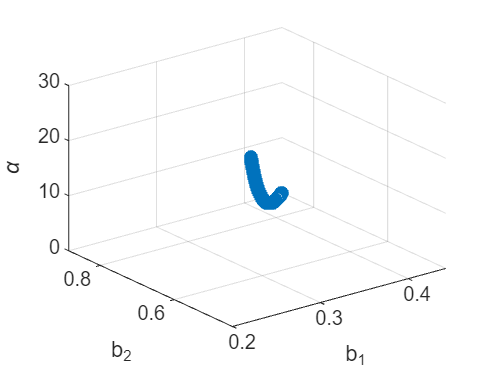


p = 2:10;
c_n = zeros(length(p),1);
for i = 1:length(p)
    p_i = p(i);
    c_n(i) = cond(hilb(p_i));% функция cond считает condition number
end
semilogy(c_n)
xlabel("matrix size");ylabel("conditional number")

Поэтому для достаточно больших размеров матрицы, решение будет неустойчиво, то есть небольшие изменения правой части будут приводить к значительным изменениям решения.

Тут опять может помочь регуляризация Тихонова.

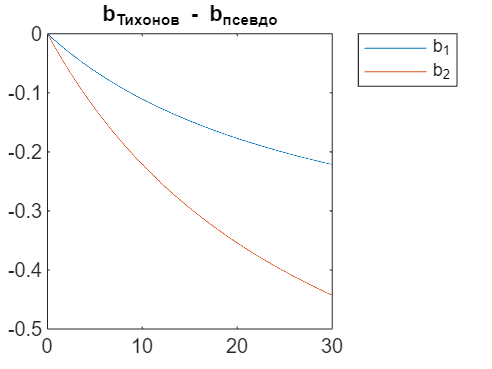

A = hilb(8)
y = ones(8,1);

alfa = 0.1
f = @(b)((A*b - y)'*(A*b - y) + alfa*b'*b)
b_optimization = fminsearch(f,rand(8,1)) % случайное положение 
% стартового вектора каждый раз приводит к разному ответу
% если alfa = 0  - регуляризация отсутсвует
norm(b_optimization)

При этом, для матрицы, близкой к сингулярной, но не сингулярной, песвдообратная матрица не очень полезна

b_pinv = pinv(A)*y

$$ans = \left(\begin{array}{ccccc} 1 & \frac{1}{2} & \frac{1}{3} & \frac{1}{4} & \frac{1}{5}\\ \frac{1}{2} & \frac{1}{3} & \frac{1}{4} & \frac{1}{5} & \frac{1}{6}\\ \frac{1}{3} & \frac{1}{4} & \frac{1}{5} & \frac{1}{6} & \frac{1}{7}\\ \frac{1}{4} & \frac{1}{5} & \frac{1}{6} & \frac{1}{7} & \frac{1}{8}\\ \frac{1}{5} & \frac{1}{6} & \frac{1}{7} & \frac{1}{8} & \frac{1}{9} \end{array}\right)$$

norm(b_pinv)

Можно понять почему так происходит, если посмотреть на решение задачи регуляризации Тихонова:


$$(A^TA + \alpha I)^{-1} A^T= V (
[\matrix{\frac{\sigma_1}{\sigma_1^2 + \alpha}  &&&&0\cr
&\ddots \cr
& &\frac{\sigma_i} {\sigma_i^2  + \alpha} &  \cr
&&&\ddots \cr
0&&&&\frac{\sigma_n}{\sigma_n^2  + \alpha}  &  \cr
}] U^ T$$


Хотя критерий неустойчивости Адамара это не тоже самое что численная неустойчивость, однко на практике математическая неустойчивость приводит к численной неустойчивости, что проявляется либо в зависимости от стартовых условий оптимизации, либо в расходимости процесса оптимизации.

## Уравнение теплопроводности

изменение запасенной в объеме энергии = поток энергии, выходящий из объема вовне + произведенная внутренними источниками энергия


$$\frac{d}{dt} \int\int\int_V \rho c (T) \, dV = - \int\int_S \vec{q} \cdot \vec{n}  dS +\int\int\int_V  Q \, dV$$


Теорема Гаусса (теорема о дивергеции) связывает суммарный поток вектора перпендикулярной повехности с суммарной дивергенцией вектора в объеме


$$\int\int_S \vec{q} \cdot \vec{n}  dS =  \int\int\int_V \nabla\cdot\vec{q}dV$$


Уравнение теплопроводности:


$$ C(T) \frac{\partial T}{\partial t}  = -\nabla \cdot\vec{q}(\vec{r}, T) + Q(T,\vec{r})  $$


$\vec{q}(\vec{r},T)$ - вектор плотности теплового потока


$$\vec{q}(\vec{r},T)=-\nabla T(\vec{r})$$


Рассмотрим одномерную задачу теплопроводности


$$\begin{cases} \matrix{
 C(T) \frac{\partial T}{\partial t}  = \frac{\partial }{\partial x}( \lambda(T) \frac{\partial T}{\partial x}) \cr 
T(x,0) = \phi(x),x   \in [0,b] \cr
T(d,t) = f(t), t \in [0,t_m] \cr
-\lambda(T(b,t))\frac{\partial T}{\partial x} (b,t) = \tilde q(t)


} \end{cases}$$


Это уравнение в частных произодных, с двумя переменными - время и координата, толщина образца $b$, $d$ - точка расположения термопары.Кроме того, мы знаем распределение температуры по толщине образца в начальный момент времени $\phi(x)$, зависимость температуры от времени на некоторой глубине $d$, которая задачется функцией $f(t)$ и зависимость от времени теплового потока через нижнюю границу $\tilde{q}(t)$.

$C(T)$ -  теплоемкость образца, она выражается через его удельную теплоемкость и плотность:$С(T) = c_v(T)\rho$. 

$\lambda(T)$ - коэффициент теплопроводности 

 Если $d=0$ - уравнение становится прямой задачей, с граничными условиями первого рода (температура) сверху и второго рода (тепловой поток) снизу. Собственно, в области $x \in [d,b]$ задача является прямой и решается однозначно. А вот в область $x \in [0,d]$ решение требуется продлить, восстановив граничные условия и температуру на верхней границе (то есть, это задача восстановления граничных условий). Задача в такой формулировке удобна, так как на практике, даже если мы ставим целью измерить температуры на поверхности слоя, термопары все равно должны заделываться на некоторую глубину под поверхностью образца, измерить температуру нагреваемой поверхности при помощи термопары невозможно.

Для программирования и решения обратных задач, удобно переписать это выражение в виде: 

$\begin{cases} \matrix{
\frac {1}{a(T)} \frac{\partial T}{\partial t}  =\frac{\partial^2 T}{\partial x^2} +   \frac{\lambda'(T)}{\lambda(T)} (\frac{\partial T}{\partial x})^2 \cr 
T(x,0) = \phi(x),x   \in [0,b] \cr
T(d,t) = f(t), t \in [0,t_m] \cr
-\lambda(T(b,t))\frac{\partial T}{\partial x} (b,t) = \tilde {q}(t)
} \end{cases}$                                                                                    **(1)**

Здесь $a(T) =\frac {\lambda(T)}{c_p(T)\rho}$  - коэффициент температуропроводности, а $\lambda'(T)=\frac {d\lambda}{dT}$. Данная форма удобна для решения обратных задач, так как мы будем предполагать полиномиальную зависимость теплопроводности от температуры, а , как известно, для полиномов очень легко и быстро считается производная.

Предполжим, что температура у нас имеет следующую форму, это матрица $[T]$, элемент $T_l^n$ которой, стоящий на $m$ -й строке $n$ - го столбца представляет собой температуру в $m$ - й момент времени для точки с $n$ - й координатой. Данная матрциа имеет размерность $M \times N$.

Метод конечных разностей. Для аппроксимации производной по времени воспользуемся выражением имеющим порядок точности $O(\Delta t)$:


$$\[
\frac{\partial T}{\partial t}_{mn} \approx \frac{T^{m+1}_n - T^{m}_n}{\Delta t}
\]$$


То есть, берутся температуры n - го элемента сетки в m и m+1 - й моменты времени.

В матричной форме конечной-разностный оператор первого порядка:


$$\[
D_t = \frac{1}{\Delta t}[
\matrix{
-1 & 1 & 0 & \cdots & 0 & 0  \cr
0 & -1 & 1 & \cdots & 0 & 0\cr
\vdots & & \ddots & \ddots & \vdots & 0\cr
0 & \cdots & 0 & -1 & 1 & 0\cr
0 & \cdots & \cdots & 0 & -1 & 0
}
]$$


Данная матрца имеет размерность $(M - 1)\times M$.  Данный оператор действует на столбец и возвращает вектор размером $(M - 1)\times 1$ значений производной. Если он действует на матрицу $[T]$, мы соотвественно получим матрицу производных по времени для температуры от координаты. 

Для расчета первой производной по координате можно воспользоваться  выражением более высокого порядка точности ($O(\Delta x ^2)$):


$$\[
\frac{\partial T}{\partial x} _{mn} \approx \frac{T^{m}_{n-1} - T^{m}_{n+1}}{2\Delta x}
\]$$



$$\[
D_{tsym} = \frac{1}{2\Delta x}[
\matrix{
0 & 1 & 0 & \cdots & 0 \cr
1 & 0 & -1 & \cdots & 0 \cr
\vdots & & \ddots & \ddots & \vdots \cr
0 & \cdots & 1 & 0 & -1 \cr
0 & \cdots & \cdots & 0 & -1
}
]$$


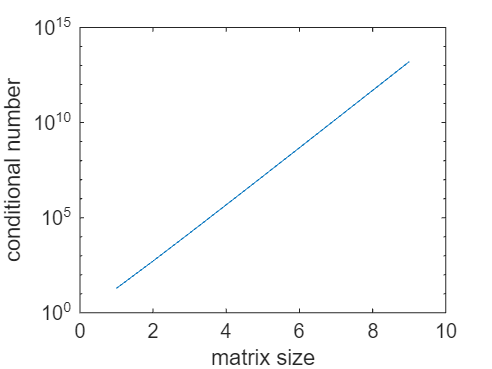

N = 3;
M = 40;
a = zeros(M,N)
D = Dt(M)
Dsym = Dtsym(M)
D*rand(M,N)
ppp = [2,0.4,4,1,2];
x = linspace(0,1,M)';

y = polyval(ppp,x);
h = x(end) - x(end-1)
y_der = polyval(polyder(ppp),x);
xmean = (x(1:end-1) + x(2:end))/2;

A =     1.0000    0.5000    0.3333    0.2500    0.2000    0.1667    0.1429    0.1250
    0.5000    0.3333    0.2500    0.2000    0.1667    0.1429    0.1250    0.1111
    0.3333    0.2500    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000
    0.2500    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909
    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833
    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769
    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714
    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667


plot(x,y_der,"b",xmean,D*y/h,"or",xmean(2:end),Dsym*y/h,"*g")

Теперь посмотрим на оператор второй производной:


$$\[
\frac{\partial^2 T}{\partial x^2}_{mn} \approx \frac{T^{m+1}_{n+1}  - 2T^{m+1}_{n} +T^{m+1}_{n-1}}{\Delta x^2}
\]$$



$$\[
D^2 = \frac{1}{\Delta x^2}
[\matrix{
-2 & 1 & 0 & \cdots & 0 \cr
1 & -2 & 1 & \cdots & 0 \cr
0 & 1 & -2 & \cdots & 0 \cr
\vdots & \vdots & \vdots & \ddots & 1 \cr
0 & 0 & 0 & 1 & -2
}
]$$


Уравнение (1) может быть записано в матричной форме:


$$[\frac {1}{a(T)} ]D_t \cdot [T]  =[T]\cdot D_{xx}+   [\frac{\lambda'(T)}{\lambda(T)}]([T]\cdot D_x \circ [T] \cdot D_x)$$


$\circ$ - произведение Адамара (поэлементное умножение).

Предполагаем, что теплофизические свойства определяются по температурам в предыдущий момент времени. Построим сетку для координаты и времени:


$$x_n = n\Delta x, n\in 0...N$$
 


$$t_m = m\Delta t, m\in 0...M$$
 

Задача состоит в том, чтобы выразить через производную по времени распределение температуры по толщине образца в $m+1$-й момент времени, через распределение температуры в $m$ - й момент времени. 

Подставив выражения для производных в уравнение (1) получим:


$$\frac {1}{a_{mn}\Delta t} (T^{m+1}_n - T^{m}_n)  =\frac{1}{\Delta x^2} (T^{m+1}_{n+1}  - 2T^{m+1}_{n} +T^{m+1}_{n-1})+   \frac{1}{4\Delta x^2} \frac{\lambda'_{mn}}{\lambda_{mn}} (T^{m}_{n-1} - T^{m}_{n+1})^2 $$



$$ (T^{m+1}_n - T^{m}_n)  =F_{mn}(T^{m+1}_{n+1}  - 2T^{m+1}_{n} +T^{m+1}_{n-1})+   F_{mn}\frac{\lambda'_{mn}}{4\lambda_{mn}} (T^{m}_{n-1} - T^{m}_{n+1})^2 $$



$$F_{mn}=\frac{a_{mn}\Delta t}{\Delta x^2} $$


Выразим из этого уравнения температуру для следующего момента времени:


$$ T^{m+1}_n (1 + 2F_{mn})   - F_{mn}T^{m+1}_{n+1}  + F_{mn}T^{m+1}_{n-1}  =  T^{m}_n +   F_{mn}\frac{\lambda'_{mn}}{4\lambda_{mn}} (T^{m}_{n-1} - T^{m}_{n+1})^2 $$


Пусть у нас есть вектор- столбец распределения температуры по толщине в текущий момент времени $\vec{T}^m$


$$B_m\vec{T}^{m+`1} = \vec{T}^m + K^D[H\vec{T}^m\circ H\vec{T}^m]=\vec{b}^m(\vec{T}^m)$$



$$
{B}_m = [
\matrix{
1 + 2F_{m1} & -F_{m1} & 0 & \cdots & 0 \cr
-F_{m2} & 1 + 2F_{m2} & -F_{m2} & \cdots & 0 \cr
0 & -F_{m3} & 1 + 2F_{m3} & \cdots & 0 \cr
\vdots & \vdots & \vdots & \ddots & -F_{m,N-1} \cr
0 & 0 & 0 & -F_{mN} & 1 + 2F_{mN}
}
]$$


Вектор $\vec{b}^m$ - нелинейная функция вектора распределения температуры по толщине слоя на предыдущем шаге.

Начальное условие:


$$T_n^0 = \phi(x_n)$$


Для учета граничных условий и расчета теплового потока, рекомендуется использовать разностные соотношения второго порядка точности, учитывающие накопление тепла на предыдущем шаге:

$q^{m+1}=\frac{\lambda_0^m}{\Delta x}(T_0^{m+1} - T_1^{m+1}) + C_0^m\frac{\Delta x}{2\Delta t}(T_0^{m+1} - T_0^m) $ - тепловой поток сверху

$\tilde q^{m+1}=\frac{\lambda_N^m}{\Delta x}(T_N^{m+1} - T_{N-1}^{m+1}) + C_0^m\frac{\Delta x}{2\Delta t}(T_N^{m+1} - T_N^m) $ - тепловой поток снизу

В матричной форме данные уравнения будут иметь вид

FUNTIONS

function D = Dt(M)

alfa = 0.1000

% M- number of input matrix rows

f = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+alfa*b'*b)


    D = zeros(M-1,M);

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 1.392174 



b_optimization =    -0.3333
    0.8003
    1.0240
    1.0567
    1.0312
    0.9870
    0.9375
    0.8886


    D(diagonal_inds(0,M-1,M)) = -1;
    D(diagonal_inds(1,M-1,M)) = 1;
end

ans = 2.5735

function D = Dtsym(M)
% M- number of input matrix rows
    D = zeros(M-1,M);

b_pinv = 1.0e+05 *

   -0.0001
    0.0050
   -0.0756
    0.4620
   -1.3860
    2.1622
   -1.6817
    0.5148


    D(diagonal_inds(-1,M-1,M)) = -1/2;

ans = 3.1477e+05

a =      0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0


D =     -1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0    -1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0    -1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0    -1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0    -1  

Dsym =          0    0.5000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.5000         0    0.5000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0   -0.5000         0    0.5000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 

ans =    -0.4012    0.3168    0.2927
   -0.0221   -0.7100   -0.4922
    0.3284    0.9071    0.1092
    0.4320   -0.1827   -0.0806
   -0.3559   -0.2049   -0.0032
   -0.5192   -0.3750    0.1318
    0.0209    0.3141    0.5535
    0.7512    0.0199   -0.4092
   -0.3537    0.4764   -0.0671
   -0.0687   -0.1394   -0.2247


h = 0.0256

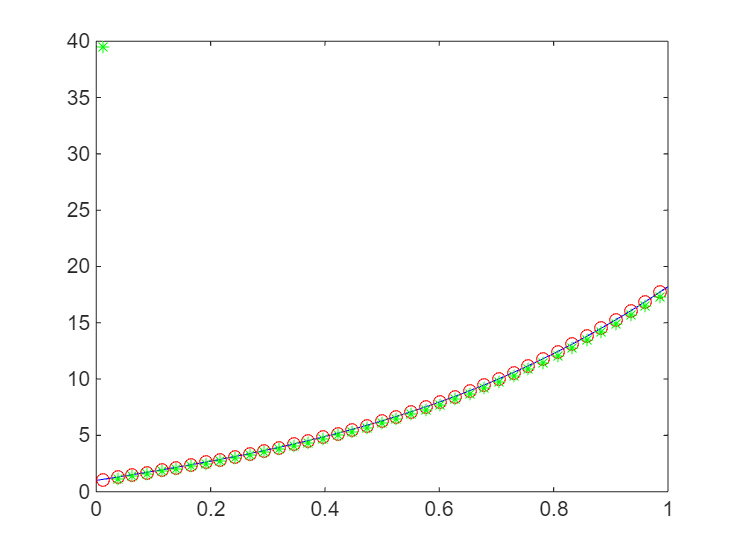

    D(diagonal_inds(1,M-1,M)) = 1/2;
end
function D = D2t(N)
    D = zeros(N,N);
    D(diagonal_inds(0,M-1,M)) = -2;
    D(diagonal_inds(1,M-1,M)) = 1; 
    D(diagonal_inds(-1,M-1,M)) = 1;
end
function indices = diagonal_inds(diagonal_index,rows_number, columns_number)
    % diagonalIndicesRect returns linear indices of the k-th diagonal of an m x n matrix
    % m - number of rows
    % n - number of columns
    % k - diagonal number (0 = main, >0 above main, <0 below main)
    %
    % Linear indices are returned for the elements along the specified diagonal,
    % respecting matrix dimensions.
    
    if diagonal_index >= 0
        % Diagonal above or on main
        len = min(rows_number, columns_number-diagonal_index);
        rowIdx = 1:len;
        colIdx = (1:len) + diagonal_index;
    else
        % Diagonal below main
        len = min(rows_number+diagonal_index, columns_number);
        rowIdx = (1:len) - diagonal_index;
        colIdx = 1:len;
    end
    
    % Convert row and column indices to linear indices for column-major order
    indices = sub2ind([rows_number columns_number], rowIdx, colIdx);
end